theta = -pi:0.01:pi;

% Original radiation pattern calculation
U = sin(theta).^2 .* (2 .* sin(pi .* cos(theta)) + 1).^2;

disp(min(U));

   1.4998e-32



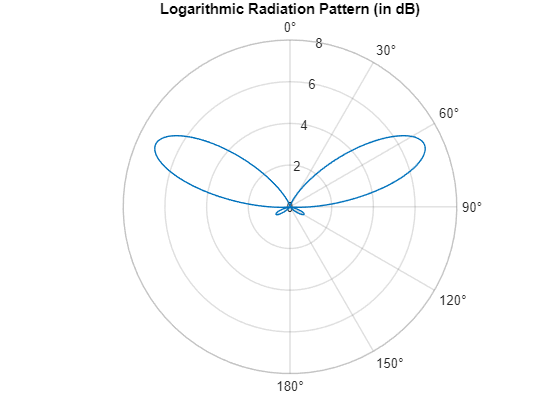


figure;
polarplot(theta, U);
ax = gca;
ax.ThetaZeroLocation = 'top'; % Set 0 degrees to the top
ax.ThetaDir = 'clockwise';    % Change direction to clockwise
ax.ThetaTick = -180:30:180;   % Set angle ticks from -180 to +180 degrees

% Optional: Label to indicate logarithmic scale
title('Logarithmic Radiation Pattern (in dB)');